# Lab 05 Control tools- root locus

Brandon Tighe - MECH 529

02/22/2021

clc 
clear

## Task 1- Plot the root locus for a given system

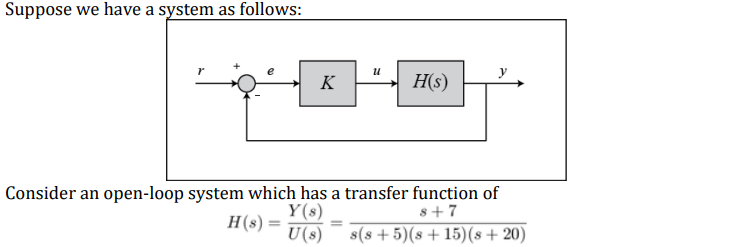


% plot root locus
s = tf('s');
sys = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
rlocus(sys)
axis([-22 3 -15 15]) 

% plot the zeta-omega n grid
zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)

% plot root locus
[k,poles] = rlocfind(sys) 

Select a point in the graphics window


selected_point = -13.3211 - 0.0929i

k = 196.9506

poles =   -21.2901
  -13.3188
   -4.2460
   -1.1451


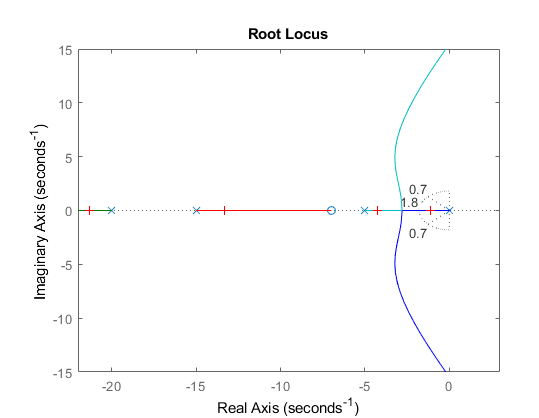

## Task 2- Designing Proportional Controllers in MATALB control system designer

s = tf('s');
plant = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20)); 

% use control system designer
controlSystemDesigner(plant) 

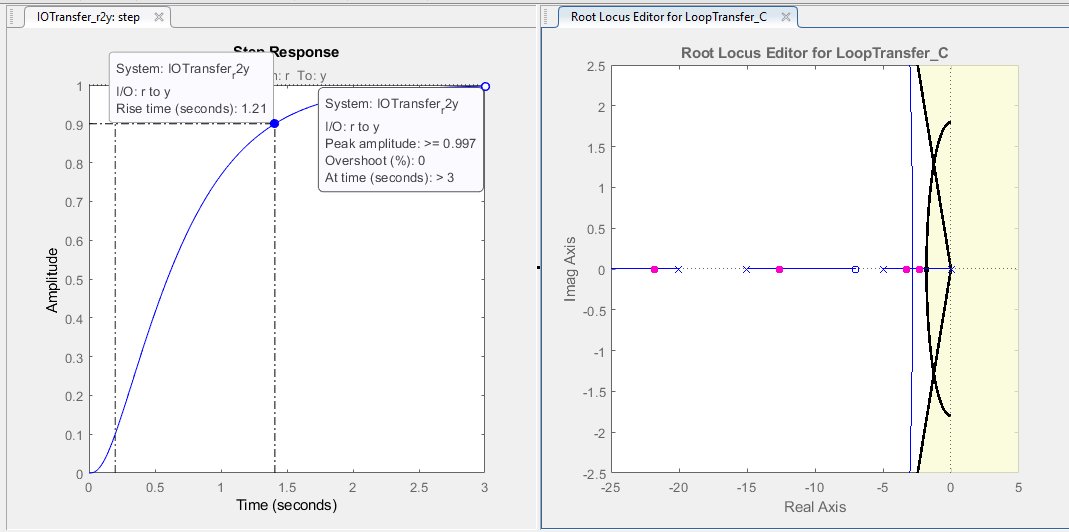

## Task 3- Designing Dynamic Controllers with Control system designer

s = tf('s');
sys4 = 1/(s+1)^2 ;
controlSystemDesigner(sys4) 

Compensator for PD controller [ (K(s+z1) ]

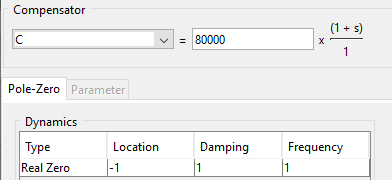

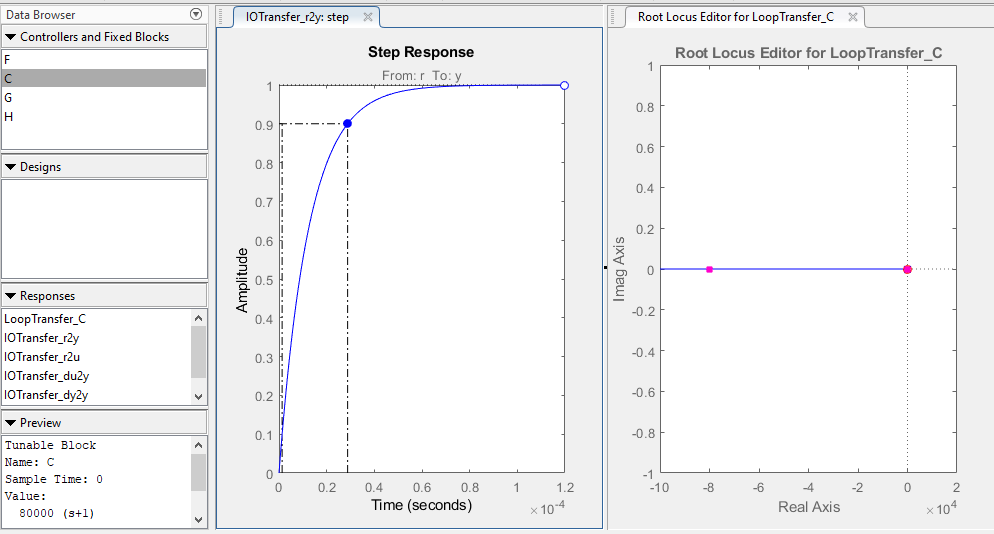

--------------------------------------------------------------------------------------------------------------------------------------------------------

sys5 = 1/(s+1)/(s+2);
controlSystemDesigner(sys5) 

Compensator for PI controller [ (K/s)*(s+z1) ]

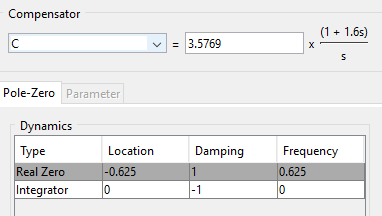

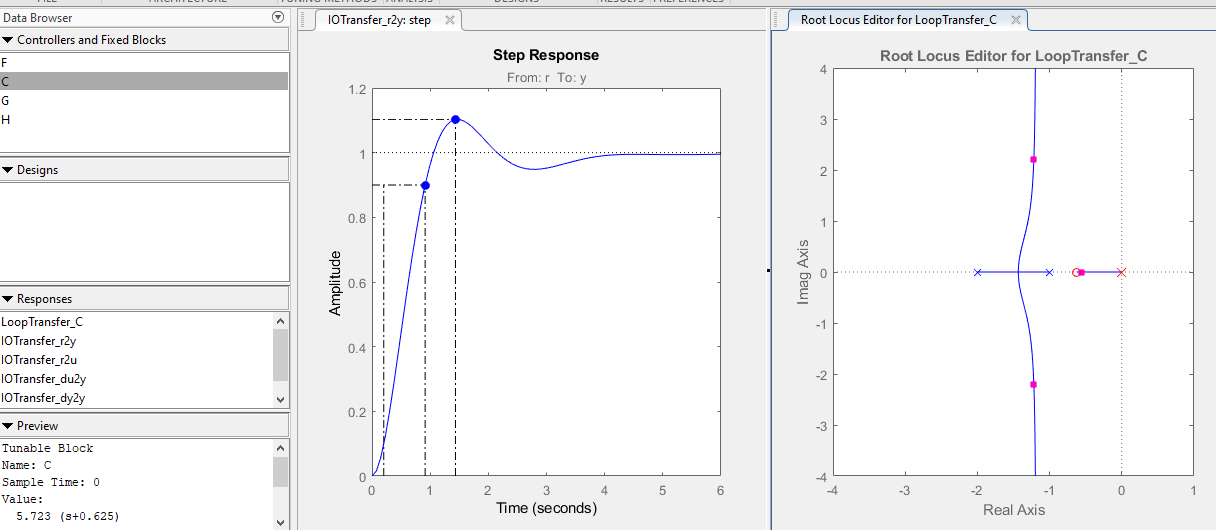

--------------------------------------------------------------------------------------------------------------------------------------------------------

sys6 = 1/s^2 

sys6 =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



controlSystemDesigner(sys6)

Compensator for PID controller [ (K/s)*(s^2 + as + b) ]

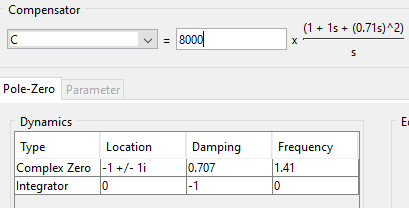

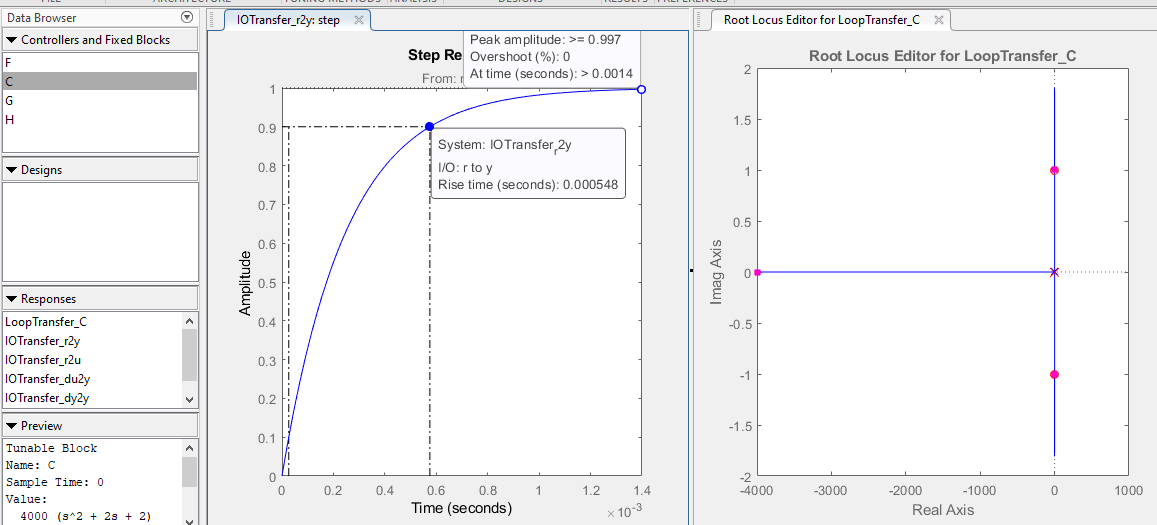

## Task 4- Homework 1A

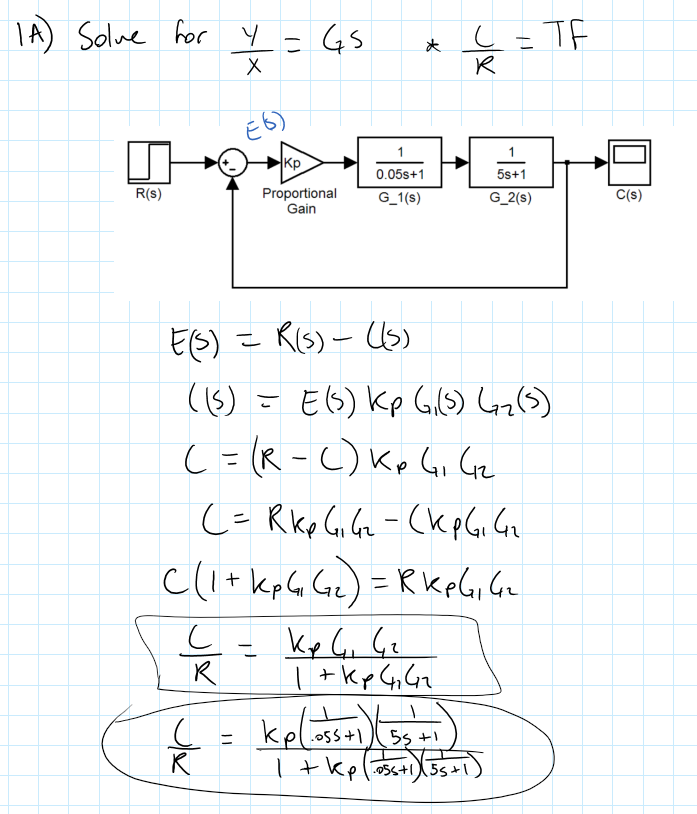

## Task 4- Homework 1B

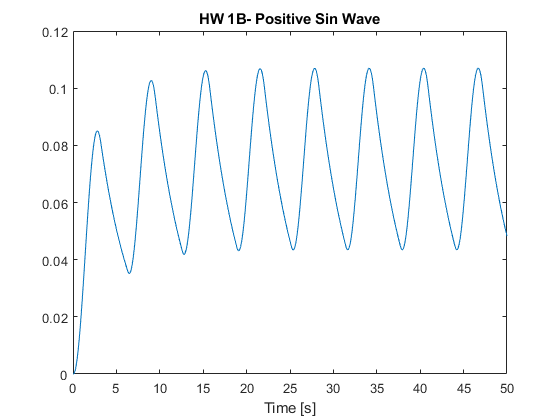

open_system('Lab05Hw1')
load_system('Lab05Hw1');
sim('Lab05Hw1');
clf
figure(1)
Lab05Hw1data= ans.ScopeData;
plot(Lab05Hw1data(:,1),Lab05Hw1data(:,2))
title("HW 1B- Positive Sin Wave")
xlabel("Time [s]")

Task 1B block diagram

## Task4- Homework 2 A-D

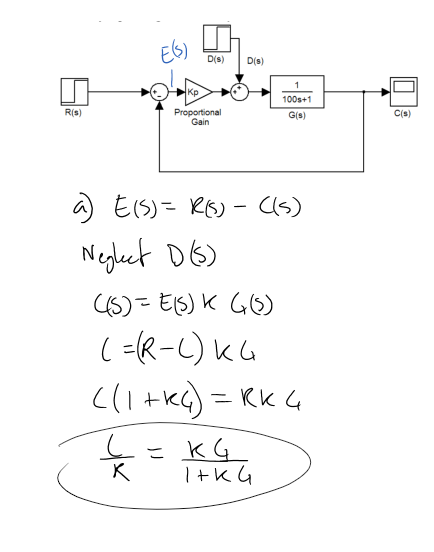

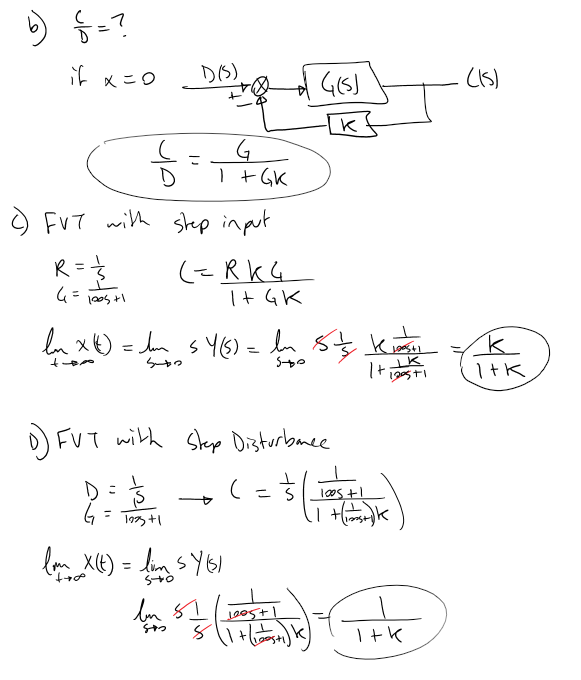

## Task4- Homework 2E

open_system('Lab05Hw2')
Kp=1;
Kp2=2.0229;
load_system('Lab05Hw2');
sim('Lab05Hw2');
figure(3)
clf
Lab05Hw2data= ans.ScopeData;
subplot(2,1,1)
plot(Lab05Hw2data(:,1),Lab05Hw2data(:,2))
axis([0 200 0 1.5])
grid on
title("HW2E - Kp = 1")
xlabel("Time [s]")


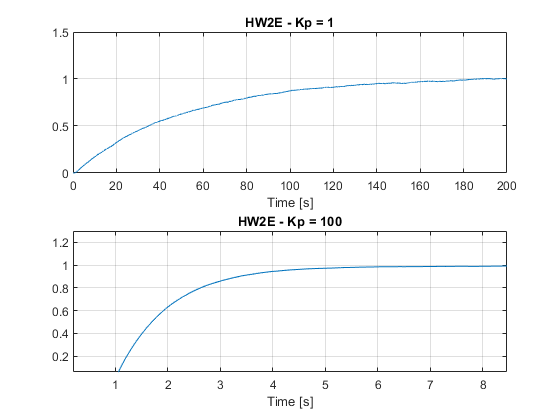

Kp=100;
Kp2=1;
load_system('Lab05Hw2');
sim('Lab05Hw2');
Lab05Hw2data= ans.ScopeData;
subplot(2,1,2)
plot(Lab05Hw2data(:,1),Lab05Hw2data(:,2))
axis([0 10 0 1.5])
grid on
title("HW2E - Kp = 100")
xlabel("Time [s]")

Task 2E block diagram